# Метод инвариантного погружения

[folder,name] = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(folder,name+"_deps"));

### Школьная задачка


$$\sqrt{3+\sqrt{3+ \sqrt{3...}}} -?$$



$$F(n) = \sqrt {3 +_n \sqrt{3+_{n-1} ...\sqrt {3+_1\sqrt{3}}}}} $$



$$F( n \rightarrow\infty)=?$$


fval(15) % вариант процедурный 

fval_rec(0,0,15) % враиант через рекурсию

plot(arrayfun(@fval,1:15),Marker = 'diamond',linewidth=3)
title(" F(n) ")
xlabel("Число элементов")
ylabel("Значение функции")



$$F(n) = \sqrt {3 +_n \sqrt{3+_{n-1} ...\sqrt {3+_1\sqrt{3}}}} =\sqrt{3+F_{n-1}$$



$$X= \sqrt{3+X}, X^2-X-3=0 \ (X>0)$$



$$X= \frac{-1\pm\sqrt{1+12}}{2}$$


0.5*(1+sqrt(13))

Предполагаем, что решение нам известно и смотрим что будет если к нему добавить еще один элемент.

## Последовательность Фибоначчи

$X_{n+1}=X_{n} + X_{n-1}$ , $X_1=1,X_2=1$

### Процедурное решение и рекурсия

Процедурное решение - суммирование в цикле.

Функциональное решение - суммирование при помощи рекурсии

fib_dir(7)
fib_rec(7)

tic;fib_dir(35);toc
tic;fib_rec(35);toc

Почему рекурсия медленно работает можно понять если посмотреть граф вызова

plotFibTreeGraph(5)

### Memoization pattern

Как видно из графа для последовательности фибоначчи, при рекурсии происходит частое повторение одного и того же паттерна (так как следующий элемент выражается через предыдущие). Соотвественно, идея состоит в том, чтобы хранить отдельно уже посчитанные элементы последовательности, чтобы не надо было их пересчитывать

#### Класс dictionary

Словарь  - это коллекция данных, организованная по принципу ключ-элемент, данные доступны по ключу, разные элементы не могут иметь один ключ. Словари адаптированы под возможность раширения множества.

d = dictionary("a",10)
f = @(d,x,y)insert(d,x,y)

% словарь, как и остальные базовые коллекции (struct,cell и др.) 
% используют pass-by-value
f(d,"b",34)
d

Обертка ("wrapper") для стандартного словаря в матлаб, чтобы нам удобнее было писать данные 

Рекурсивная функция с запоминанием значений

fib_mem(30)

clear fib_mem

#### Класс-"запоминатель"

Функция **fib_mem **повзоляет решать рекурсивную задачу фибоначчи с запомимнаем, она специализрованая, при помощи ООП можно сделать некоторый универсальный класс, который позволяет нам использовать произвольную рекурсивную функцию. 

fib2 = @(N,f) f(N-2) + f(N-1); % создаем анонимную функцию
m = memoizer_class(fib2,[1 2],[1 1]); % передаем мемоизатору функцию и начальные условия
m.fun(45);

Одно из преимуществ способа запоминания при помощи классов, является то, что после выполнения функции все содержимое словаря может быть легко доступно. Построим график всех значений в словаре.

all_values = arrayfun(@(i)get(m.d,i),1:45);
plot(1:45,all_values);xlabel("N");ylabel("Fibonacci")
yscale log;

В отличие от функционального решения, класс -запоминатель является универсальным, например, мы можем проанализировать устойчивость рекуррентной последовательности в зависимости от начальных условий:

fib2 = @(N,f) f(N-2) + f(N-1); % создаем анонимную функцию
y2_ = -0.8:0.1:0.8;
NMAX = 30;
f_max = zeros(length(y2_),NMAX); % тут будут хранится полученные значения
counter = 0;
for y2 = y2_
    counter = counter+1;
    m = memoizer_class(fib2,[1 2],[1 y2]); % передаем мемоизатору функцию и начальные условия
    m.fun(NMAX);
    f_max(counter,:) = arrayfun(@(i)get(m.d,i),1:NMAX);
end
plot(1:NMAX,f_max')
legend("y2=" + string(y2_))

Или изучить параметрическую устойчивость разностной схемы

f_new = @(N,f,a,b) a*f(N-2) + b*f(N-1)
a = 1:-0.1:0.1;
b = -1:0.1:-0.1;
NMAX = 100;
f_max = zeros(length(a),length(b),NMAX); % тут будут хранится полученные значения

for i = 1:length(a)
    for j=1:length(b)
        ai = a(i);bj = b(j);
        fib2 = @(N,f) f_new(N,f,ai,bj);
        m = memoizer_class(fib2,[1 2],[1 1]); % передаем мемоизатору функцию и начальные условия
        m.fun(NMAX);
        f_max(i,j,:) = arrayfun(@(i)get(m.d,i),1:NMAX);
    end
end

sc = 81;
contourf(b,a,log(abs(f_max(:,:,sc ))))

NMAX=40;
t_fib_dir= zeros([NMAX,1]);t_fib_rec = t_fib_dir;t_fib_mem_rec=t_fib_rec;
t_fib_mem_class = t_fib_dir;
fib_mem_class = memoizer_class(fib2,[1 2],[1 1])
for n = 1:NMAX
     tic;fib_rec(n);t_fib_rec(n) = toc;
     tic;fib_mem(n);t_fib_mem_rec(n) = toc;
     tic;fib_dir(n);t_fib_dir(n) = toc;
     tic;fib_mem_class.fun(n);t_fib_mem_class(n)=toc;
end
plot(1:NMAX,t_fib_rec,1:NMAX,t_fib_mem_rec,1:NMAX,t_fib_dir,1:NMAX,t_fib_mem_class)
yscale log
legend(["Рекурсия"  "Рекурсия с памятью" "Прямое суммирование" "Memoizer"])
xlabel("Число элементов последовательности")
ylabel("Время выполнения, с")

### Уравнение переноса излучения в двухпотоковом приближении

Будем решать следующую задачу:

Пусть у нас есть некоторая одномерная среда длиной $X$, в которой распространяется излучение (поток частиц). Вероятность того, что частица  на участке пути длиной $\Delta$ равна $\sigma \cdot \Delta$. Доля частиц, рассеиваемых вперед (продолжающих двигаться в томже направлении, что и до рассеяния ) равна $f$, а в противоположном  - $b$ ($f + b = 1$). Все параметры ($\sigma,f,b$) могут зависеть от координат. Излучение падает с левого края.  

#### Классический подход

Будем рассматривать задачу в двух потоковом приближении, то есть у нас есть плотность излучения движущегося вправо ($U$) и влево  - $V$. 

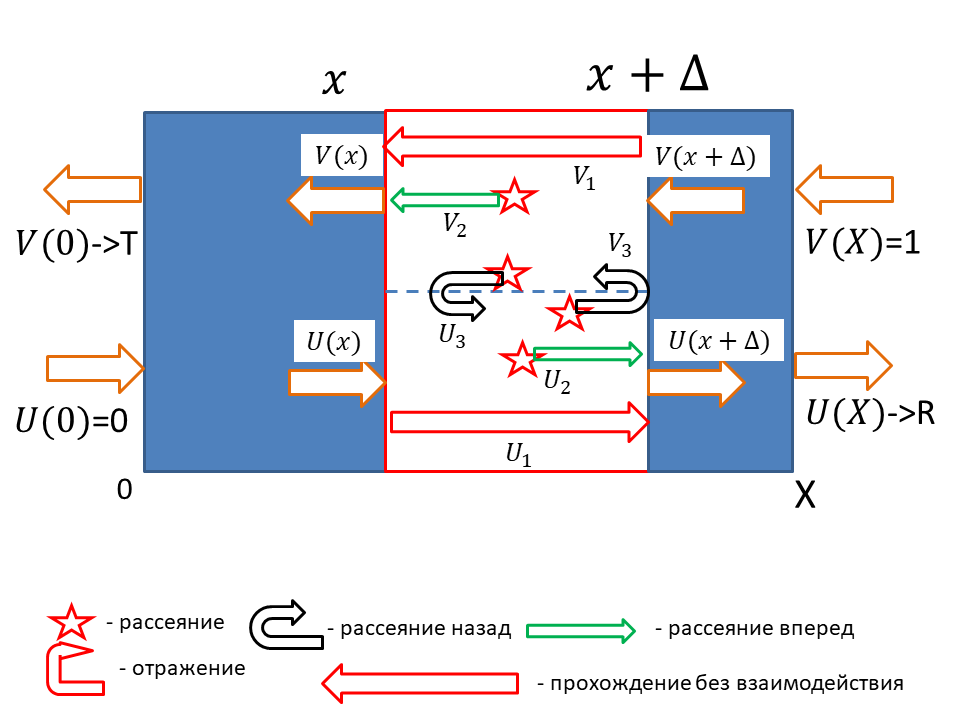

Рассмотрим небольшой участок пути излучения длиной $\Delta$ и, чтобы сформулировать дифференциальное уравнение переноса, рассмотрим потоки излучения на этом участке. Поток излучения в объеме этого элемента формулируется как сумма потоков движущихся  влево и вправо:

Для излучения, движущегося вправо:


$$U(x+\Delta)=U_1 + V_3 + U_3$$


$U_1 = (1-\sigma\Delta)U(x)$ - излучение, которое пролетает через слой не рассеиваясь ($1 - \sigma\Delta$) - вероятность того, что рассеяния не произойдет (единица минус вероятность рассеяния $\sigma\Delta$).

$U_2 =f \sigma\Delta U(x)$  - доля излучения, рассеянного вперед

$U_3 =b \sigma\Delta V(x+\Delta)$ - часть потока, идущего влево, рассеянная назад (для потока, идущего вправо - это попутное направление).


$$U(x+\Delta) - U(x)=\sigma\Delta[(f-1)U(x) + b V(x+\Delta)] + o(\Delta)$$


Аналогично для потока вправо: $V(x) = (1-\sigma \Delta)V(x+\Delta) +f \sigma\Delta V(x+\Delta) + b\sigma\Delta U(x)$


$$V(x+\Delta) - V(x)=\sigma\Delta[- b U(x) - (f-1)V(x+\Delta)] + o(\Delta)$$


Теперь можно поделить на $\Delta$ и устремить его к нулю, что даст систему дифференциальных уравнений:


$$\begin{cases} \matrix{\frac{dU}{dx} = \sigma [(f-1)U(x) + b V(x)] \cr \frac{dV}{dx} = \sigma[ -b U(x) - (f-1)V(x)]  } \end{cases} $$


Удобно систему переписать в виде одного векторного уравнения: 

$\frac{d}{dx} \vec{Y} = \sigma[ \matrix{ f-1 & b \cr -b & -(f-1)} ]\vec{Y}; \ \ \vec{Y}=  \matrix{U \cr V}$                                        (1)


$$\frac{d}{dx} \vec{Y} = T\vec{Y}$$


Граничные условия :

$U(0)=0$  - слева излучение не падает

$V(X)=1$- справа излучение падает

Это краевая задача 


$$\frac{d}{dx}\vec{Y}=f(x,\vec{Y})$$


$G(\vec{Y}(0),\vec{Y}(X))=\Gamma\cdot[\vec{Y}(0);\vec{Y}(X)] = \vec{0}$ - граничные условия ($x=0, x=X$  - гранцы области) 

В нашем случае :

$f(x,\vec{Y}) = T(x)\vec{Y}$ (если $\sigma,f,b$ не зависят от координат, то $T$ - постоянная матрица) 

Граничные условия:


$$[\matrix{1 & 0\cr 0 & 1}]\cdot [\matrix{U(0) & U(X)\cr V(0) & V(X)-1 }]=[\matrix{0\cr 0}]$$


Матлаб имеет несколько численных методов для решения краевых задач.

Так как правая часть у нас имеет некоторые параметры, сделаем функцию, которая оборачивает конкретные знаечния параметров и возвращает анонимную функцию в нужной форме, правая часть нашего дифференциального уравнения:

Граничные условия в форме:

Также для решения кравевых задач требуется стартовая аппроксимация, мы возьмем линейную зависимость:

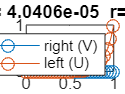

xmesh = linspace(0,1,30);% строим сетку, на которой будет
% искаться решение краевой задачи
solinit = bvpinit(xmesh, @guess); % исходное распределение
sigma=0.524;
% коэффициент f
forward_fraction = 0.776;
alfa = 10;
% коэффициент b в уравнении
backward_fraction = 1 - forward_fraction;
dy_fun = dy(sigma,alfa,backward_fraction,forward_fraction);
sol = bvp4c(dy_fun, @bcfun, solinit);
t = sol.y(2,1);
r = sol.y(1,end);
a = 1 - t - r;

plot(sol.x, sol.y,"-o" )
legend(["right (V)", "left (U)"])
title ( "albedo = "+ ...
    string(sigma/(sigma+alfa)) ...
    +"  t= "+string(t)+ ...
    "  r= "+string(r) + ...
    " a = "+string(a))

Когда потоки в объеме расчетной области найдены, коэффициент отражения это $R =U(X)= \vec{Y}(X)(1)$ - последний элемент  в функции для потока, движущегося вправо.

А коэффициент пропускания:

 $T =V(0)= \vec{Y}(0)(2)$ - то есть второй элемент вектора решения на левой границе (поток, идущий с границы влево)

#### Метод инвариантного погружения для уравнения переноса излучения в двухпотоковом приближении

В действительности нам, как правило, не нужны внутренние поля, нас интересуют коэффициенты отражения и пропускания на границе. 

Поэтому будем писать уравнения сразу для отражения (для пропускания не будем, но логика там такая же).

 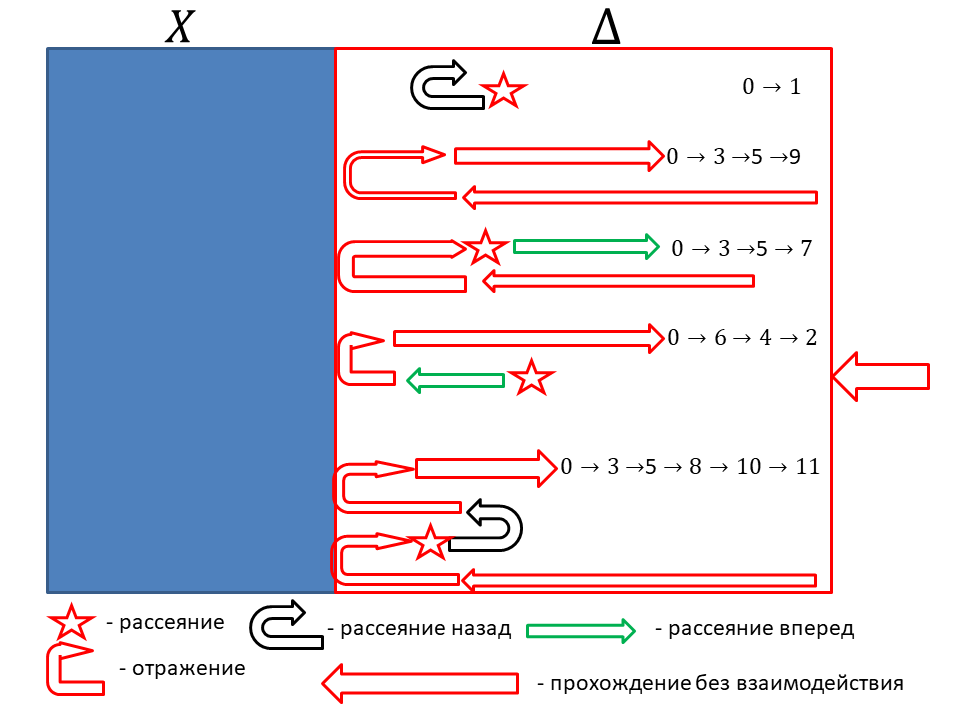

Предположим, что нам уже известно отражения от слоя толщиной $X$, растянем слой, добавив  к нему слой толщиной $\Delta$ и рассмотрим как падающее излучение может взаимодействовать с этим добавленным слоем. На картинке выше каждому элементарному акту взаимодействия соотвествует своя пиктограмма.

Излучение:

- Рассеивается назад, падающее излучения сразу выходит, рассеявшись назад (путь 0-1 на графе ниже)

- Проходит через слой нерассеявшись, отражается и опять нерассеявшись выходит из слоя (0-3-5-9)

- Проходит не рассявшись, отражается и рассеивается вперед (0-3-5-7)

- Рассеивается вперед, отражается, проходит нерассеявшись (0-6-4-2)

- Проходит, отражается,рассеивается назад,отражается,проходит без рассеяния (0-3-5-8-10-11)

Ниже приведен направленный граф рассеяний в добавленном слое. Каждый узел - единичный акт взаимодействия между излучением и добаленным слоем среды толщиной $\Delta$. 

$(1 - \sigma\Delta)$ - прямое прохождение слоя без рассеяния

$f\sigma\Delta$ - рассеяние вперед

$b\sigma\Delta$ - рассеяние назад

$R$ - отражение от слоя толщиной $X$

 Использованная для построения графа функция **inv_emb_refl_graph **возвращает:

 G - сам граф

real_leafNodes - узлы, вносящие вклад первого порядка в отражение

dead_leafNodes - узлы, вносящие вклад второго порядка в отражение

p - картинка (для объекта типа направленный граф (класс **digraph **в матлаб)

[G,real_leafNodes,dead_leafNodes,p] = inv_emb_refl_graph();

Синие узлы  - промежуточные взаимодействия

Красные - пути, которые далее ведут к событиям второго порядка малости ($\Delta^2$)

Зеленые узлы - те, которые приводят к выходу излучения на поверхность из добавленного слоя и дают вклад первого порядка.

Зеленый квадратик "0" - узел, соотвествующий акту падения излучения на добавленный слой.

Таким образом, пути от зеленого квадратика к любому из зеленых кружочков дадут нам вклад первого порядка в отражение.

Матлаб позволяет анализировать пути в графах между узлами. Нас интересуют пути между **real_leafNodes **зелеными кружочками и стартовой точкой.

pat = digitsPattern(1,2)+":";
disp("Ближайшие пути обратно на поверхность:")
for i =1:height(real_leafNodes)
    ppath = shortestpath(G,"0",real_leafNodes{i,1}{1}); % ищет пути между узлами
    out_str = join(ppath,[' ',char(8594),' ']);
    out_str = replace(out_str,pat,"");
    out_str = strrep(out_str, '\sigma', char(963)); % sigma σ
    out_str = strrep(out_str, '\Delta', char(916)); % delta Δ
    disp(out_str)
end

Просуммируем все полученные ветки (только надо выкинуть те, которые дают второй порядок по $\Delta$)


$$R(X+\Delta) = b\sigma\Delta + (1-\sigma\Delta)\cdot R \cdot(1-\sigma\Delta)+(1-\sigma\Delta) \cdot R \cdot f\sigma\Delta+f\sigma\Delta \cdot R \cdot (1-\sigma\Delta) + 
(1-\sigma\Delta)\cdot R \cdot b\sigma\Delta \cdot R \cdot (1-\sigma\Delta)$$


После простых преобразований, а также занулив все члены второго порядка получим выражение для коэффициента отражения "расширенного" слоя через коэффициент отражения исходного слоя:


$$R(X+\Delta) = R(X) +\sigma\Delta[ b   + 2(f-1)R(X) + R^2b(X)]                  $$


В форме дифференциального уравнения:


$$\frac{d}{dx} R(x) = \sigma[b+2(f-1)R(x)+R(x)^2]$$


Какое граничное условие? Если исследуемый слой полностью пропадет, то отражение от него будет равно нулю.


$$R(0)=0$$


Аналогично можно сформулировать уравнение для пропускания (оно складывается из прохождения без изменений и прохождения излучения отраженного от слоя и рассеянного назад в направлении распространения):


$$\frac{d}{dx} T(x)= \sigma[(f-1)+ bR(x)]T(x)$$


Граничное условие для пропускания соотвественно 


$$T(0)=1$$


Сравним одну и ту же задачу в постановке инвариантного подгружения и классической (локальной):

 
$$\begin{cases} \matrix{\frac{dU}{dx} = \sigma [(f-1)U(x) + b V(x)] \cr \frac{dV}{dx} = \sigma[ -b U(x) - (f-1)V(x)] \cr V(X)=1 \cr U(0)=0 } \end{cases} $$


И принципа инвариантности:

 
$$\begin{cases} \matrix{\frac{dR(x)}{dx} = \sigma\Delta[b+2(f-1)R(x)+R(x)^2] \cr \frac{dT(x)}{dx} = \sigma[(f-1)+ bR(x)]T(x) \cr R(0)=0 \cr T(0)=1 } \end{cases} $$


С одной стороны, кажется, что уравнение для коэффициентов отражения и пропускания хуже, чем для потоков влево-вправо, так как оно нелинейно (в первом стоит квадрат отражения, во втором  - произведение отражения и пропускания (это уравнение Рикатти, которое, вообще говоря, можно решить аналитически при помощи определенной подстановки). 

Но обратим внимание на граничные условия, первая система - это краевая задача слева от слоя принулевой координате мы знаем только поток, идущий вправо (слева на слой ничего не падает) а справа мы знаем поток, идущий влево (падает излучение). Вторая система  - это принципиально другой и значительно более простой для решения тип дфференциального уравнения - задача с начальными условиями (задача Коши)!

Решение задачи с начальными условиями в матлаб. Как правило задачи с начальными условиями описывают эволюцию процессов во времени от некоторого начального состояния до нужного (сам диффур решается, например, методом Рунге-Кутта)

Задача с начальными условиями:


$$\frac{d}{dx}\vec{Y}=f(x,\vec{Y})$$


$\vec{Y}(x) = \vec{Y_0}$ - начальные условия. 

В нашем случае:


$$\frac{d}{dx} \vec{Y} = \matrix{\sigma\Delta[b+2(f-1)Y(1)+Y(1)^2] \cr \sigma[(f-1)+ bY(1)]Y(2) }  ; \ \ \vec{Y}=  \matrix{R \cr T}$$
                                

sigma=5.484

sigma = 5.4840

% коэффициент f
forward_fraction = 0.486

forward_fraction = 0.4860

alfa = 0.637

alfa = 0.6370

% коэффициент b в уравнении
backward_fraction = 1 - forward_fraction

backward_fraction = 0.5140



%dR_fun = dRdx(sigma,alfa,backward_fraction,forward_fraction)
iem_fun = iem(sigma,alfa,backward_fraction,forward_fraction)

iem_fun = function_handle with value:
    @(x,Y)[funR(x,Y(1));funT(x,Y(1),Y(2))]


F = ode; % создаем объект решателя
F.ODEFcn =iem_fun; %dR_fun;
F.InitialValue = [0;1];% начальные условия
sol_inv = solve(F,0,1) % решаем

sol_inv =   ODEResults with properties:

        Time: [0 1.7823e-05 3.5645e-05 5.3468e-05 7.1290e-05 1.6040e-04 2.4952e-04 3.3863e-04 4.2774e-04 8.7330e-04 0.0013 0.0018 0.0022 0.0044 0.0067 0.0089 0.0111 0.0223 0.0334 0.0445 0.0557 0.0807 0.1057 0.1307 0.1557 0.1807 0.2057 … ] (1×61 double)
    Solution: [2×61 double]


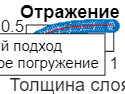


r_dir =  zeros(size(sol_inv.Time));
t_dir =  ones(size(sol_inv.Time));
for i =2:numel(sol_inv.Time)
    [r_dir(i),t_dir(i)] = r_direct(sol_inv.Time(i),alfa,sigma,forward_fraction,backward_fraction);
end
plot(sol_inv.Time,r_dir,'o',sol_inv.Time,sol_inv.Solution(1,:),'r')
legend(["Классический подход","Инвариантное погружение"])
title("Отражение");xlabel("Толщина слоя")

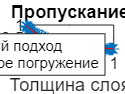

plot(sol_inv.Time,t_dir,'*',sol_inv.Time,sol_inv.Solution(2,:),'r')
legend(["Классический подход","Инвариантное погружение"])
title("Пропускание");xlabel("Толщина слоя")

#### Аналитическое решение уравнения инвариантного погружения для функции отражения.

$\frac{d}{dx} R(x) = \sigma b+2[\sigma(f-1) - \alpha] R(x)+R(x)^2$         (здесь добавлено еще поглощение $\alpha
$ - поглощение на единице длины пути)

Следует отметить, что при выводе мы нигде не ограничивали материальные функции среды, поэтому все коэффцииенты в уравнении могут зависеть от координаты.

Это уравнение общего вида:


$$\frac{d}{dx} Y(x) = A(x)+B(x)Y(x)+C(x)Y(x)^2$$
 

Хотел бы обратить внимание на глубокую связь между идеей принципа инвариантности и метода матриц рассеяния, который применяется для составления эффективных алгоритмов решения задачи рассеяния на многослойках гомогенных слоев и многослойных дифракционных решетках.

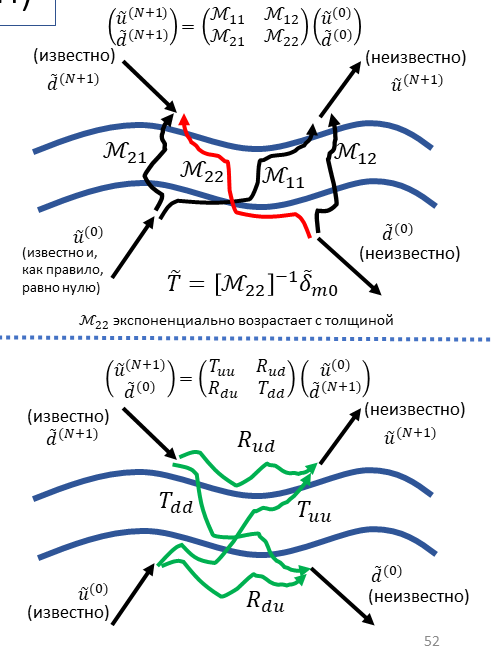

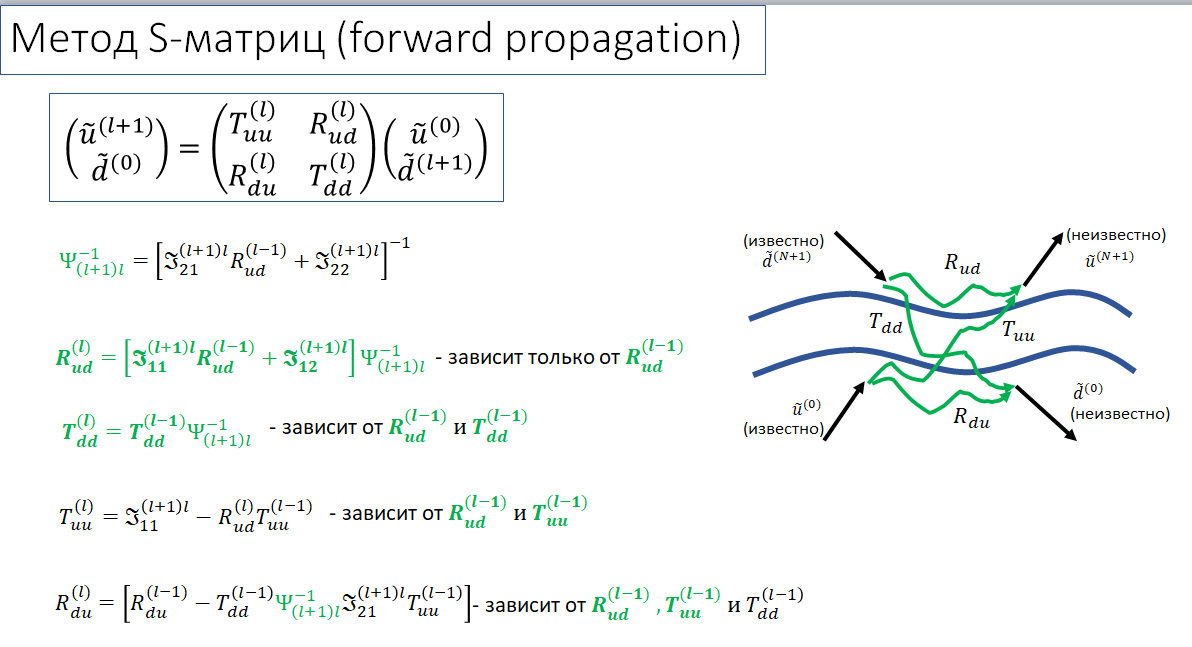

Идея метода с-матриц в том, чтобы связь между падающим полем  (на картинке выше стрелочки направлены к  объекту) и  рассеянным полем (стрелочки от объекта). В отличие от классического матричного метода, для которого ищется связь между полями идущими вверх и вниз на картинке в каждом слое.

%% задачка
function s = fval(N)
% прямое суммирование 
    a = 3;
    s = sqrt(3);
    for i = 1:N
        s = sqrt(s + a);
    end
end
function s = fval_rec(s,i,N)
% суммирование через рекурсию
    a=3; 
    if i>=N
        return
    else
         s= sqrt(a + fval_rec(s,i+1,N));
    end
end
%% последовательность фибоначчи
function val = fib_dir(N)
% процедурное решение
    if N<=2
        val = 1;
        return
    end
    val = 0;
    x1 = 1;
    x2 = 1;
    for i = 3:N
        val = x1 + x2;
        x1 = x2;
        x2 = val;
    end
end
function val = fib_rec(N)
% рекурсивное решение
    if N<=2
        val = 1;
        return
    end
    val  = fib_rec(N-1) + fib_rec(N-2);
end
function plotFibTreeGraph(n)
    % для построения графа используем рекурсию в процедурном 
    % стиле
    edges = [];
    labels = string([]);
    nodeCount = 0;
    
    % рекурсиный вызов (как в простой версии 
    % рекурсивной функции, только каждый нод добавляется в граф)
    % nested function (переменные edges,labels и nodeCount) для нее
    % глобальные
    function nodeID = buildFibGraph(num)
        nodeCount = nodeCount + 1; 
        nodeID = nodeCount;
        val = fib_mem(num);
        labels(nodeID) = "#"+string(num)+"="+string(val);
        if num <= 2
            return; 
        end
        % рекурсиный вызов
        leftID = buildFibGraph(num - 1);
        rightID = buildFibGraph(num - 2);
        
        edges(end+1, :) = [nodeID, leftID];
        edges(end+1, :) = [nodeID, rightID];
    end

    % запуск расчета
    buildFibGraph(n);
    
    % строим направленный граф 
    G = digraph(edges(:,1), edges(:,2));
    
    % рисуем граф
    figure;
    h = plot(G, 'Layout', 'layered', 'NodeLabel', labels, 'Direction','down', ...
        'Interpreter','none', 'NodeFontSize', 10, 'MarkerSize', 7);
    title(sprintf('Фибоначчи n = %d', n));
    set(gca,'XTick',[], 'YTick', []);
end
%% Решение уравнения переноса в двух-потоковом приближении

function fun = dy(sigma,alfa,b,f)
 % функция оборачивает конкретные значения параметров в анонимную функцию, 
 % которая будет использована в решателе краевых задач 
    T = zeros(2);
    T(1,1) = sigma*(f-1) - alfa;
    T(1,2) = sigma*b;
    T(2,1) = -T(1,2);
    T(2,2) = -sigma*(f-1)+alfa;
    fun = @(x,y)T*y(:);% первый аргумент  - независимая переменная 
    % второй аргумент - само значение функции
end
function res = bcfun(y0,yX)
% граничные условия для решения краевой задачи 
% для классической постановки
res = [y0(1)
       yX(2)-1];
end
function g = guess(x)
% стартовая аппроксимация
    g = [0.5*x 
        x];
end

function [r,t] = r_direct(X,alfa,sigma,f,b)
        dy_fun = dy(sigma,alfa,b,f);
        xmesh = linspace(0,X,10);
        solinit = bvpinit(xmesh, @guess);
        sol = bvp4c(dy_fun, @bcfun, solinit);
        t = sol.y(2,1);
        r = sol.y(1,end);    
end
function fun =dRdx(sigma,alfa,b,f)
    fun = @(x,R) sigma*(b + 2*(f-1)*R  + R.*R*b) - 2*alfa*R;
end
function fun = dTdx(sigma,alfa,b,f)
    fun = @(x,R,T) (sigma*((f-1)  + b*R)-alfa).*T;
end
function fun = iem(sigma,alfa,b,f)
    funR = dRdx(sigma,alfa,b,f);
    funT = dTdx(sigma,alfa,b,f);
    fun =@(x,Y) [funR(x,Y(1));
        funT(x,Y(1),Y(2))];
end
